# Second Law of Thermodynamics 

[⇦ Overview](matlab: OpenOverview) 

There are many ways to track thermodynamic information. While the first law of thermodynamics was a conservation statement, the second law of thermodynamics addresses the question of what types of thermodynamic change will happen in a system. The second law explains why your cup of coffee cools towards room temperature rather than warming itself (and cooling the room around it). It also explains why air always fills the room rather than separating with oxygen in one corner and nitrogen along the floor. Fundamentally, the second law of thermodynamics gives a direction to time. Many thermodynamic processes are irreversible because time only moves forward. 

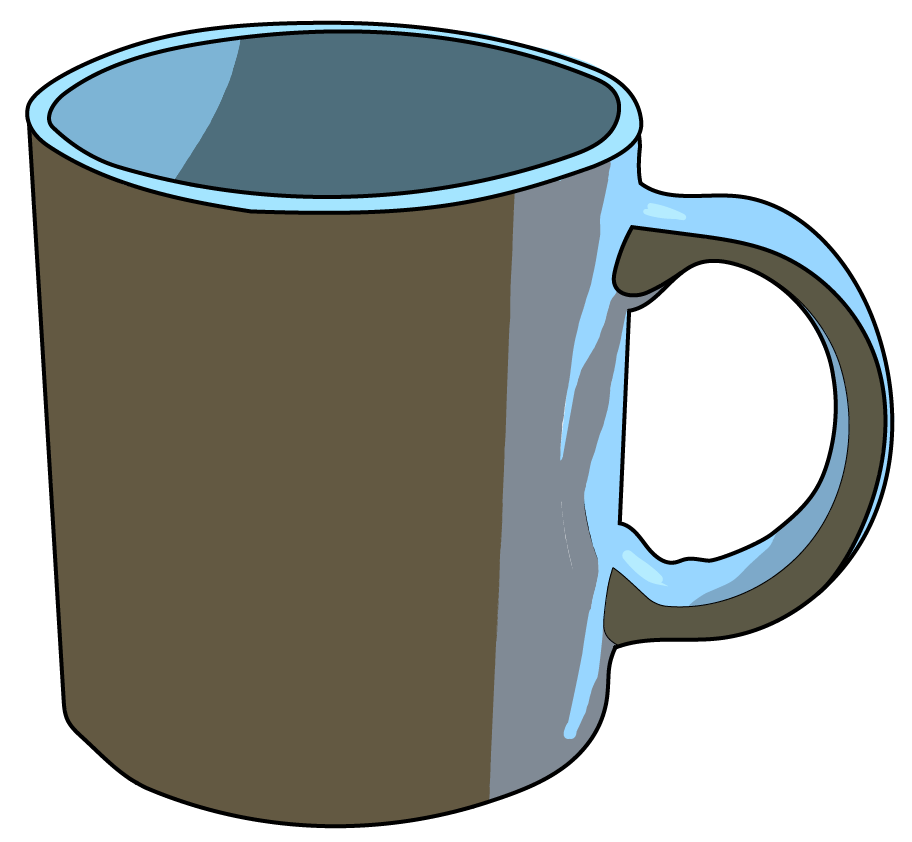

Natural processes always maximize disorder. 

**Before you get started:**

This live script is intended to be used with the code hidden. On the **View **tab of the MATLAB Toolstrip, in the **View** section, select **Hide Code**.  Alternately, select **Hide Code **using the icon  at the top right of the Live Editor pane.

 Although the code is hidden, some interactivity requires familiarity with MATLAB. If you need more instruction, consider taking [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), a free 2-hour online tutorial that teaches the essentials of MATLAB.

   For an optimal experience, follow the instructions and steps in the given sequence. Proceed to a new section only after completing the preceding one. Some sections depend on variables created in prior sections and will generate errors if they are run out of order.

## Intuitive Application of the Second Law of Thermodynamics

 **Reflect**. What does it mean that time has a single direction?

1) What happens if you take a cup of hot coffee and set it on a counter at room temperature?

2) What happens If you take a cup of ice and set it on a counter at room temperature? 

3) If you run electricity through a wire coil, what happens?

### Sources, sinks, and reservoirs

A thermal source supplies heat to a system. A thermal sink absorbs heat from a system. A thermal reservoir is a thermal source or sink with a large enough heat capacity that it can absorb or emit as much heat energy as required by a system without changing its temperature. 

  **Try**. Classify each object from the example as a source or a sink. In each example, the air in the room should be treated as a thermal reservoir.

checkTry1("unknown",1); 

checkTry1("unknown",2);

checkTry1("unknown",3);

## Thermal Efficiency

The goal of an engine is to convert energy into work. A heat engine works in a cycle:

    1) Receive heat from a high-temperature source (combustion, solar energy, etc.): $Q_{\text{in}}$

    2) Convert heat into work: $W_{\text{out}}$

    3) Eliminate remaining heat into a thermal sink: $Q_{\text{out}}$

    4) Repeat this cycle: $W_{\text{in}}$

One common structure for this is to have some fluid, called the working fluid, that shifts between liquid and gas and back over the course of the cycle. You will investigate this in more depth in [Model_Fridge.mlx](matlab:open('Model_Fridge.mlx')).

In a simplified model, this process involves heat being added to the system as $Q_{\text{in}}$ and removed from the system as $Q_{\text{out}}$. The useful work done by the engine is $W_{\text{out}}$ while the work required to keep the system cycling is $W_{\text{in}}$. Let's name the difference $W_{\text{net}} = W_{\text{out}}-W_{\text{in}}$. This engine may be worth running as long as $W_{\text{net}}>0$. Assuming that our heat engine is running as a [closed system](matlab:open('FirstLaw.mlx')), the first law of thermodynamics says that the total change in internal energy is 0. Therefore, the net heat transferred into the system must be equal to the net work output by the system:


$$W_{\text{net}} = Q_{\text{in}}-Q_{\text{out}}$$


$Q_{\text{out}}$ is the amount of heat wasted by the system to be able to complete the cycle. We can quantify this waste with the thermal efficiency:


$$\displaystyle \eta_{\text{thermal}} = \frac{W_{\text{net}}}{Q_{\text{in}}} = \frac{Q_{\text{in}}-Q_{\text{out}}}{Q_{\text{in}}} = 1-\frac{Q_{\text{out}}}{Q_{\text{in}}}.$$


## The Second Law of Thermodynamics (Kelvin-Planck Statement)

    *It is impossible for any device that operates on a cycle to receive heat from a single reservoir and produce a net amount of work. *[1]

This is equivalent to the intuition that you had above: hot coffee will cool down to the temperature of its surrounding thermal sink and cold ice will warm up to the temperature of its surrounding thermal source. You cannot set down a cup of room-temperature coffee next to a glass of water and extract heat from the water to warm up the coffee and simultaneously create ice. 

Consider a piston operating in a cycle:

syms t t0
mySpeed = 10;
isAdiabatic = 0 ;
if mySpeed*500>140
    maxTime = 2*floor(140/mySpeed);
else
    maxTime = 1000;
end
halfTime = maxTime/2;
M(t) = int(mySpeed,t0,0,t)+50;
H(t) = piecewise(mod(t,maxTime)<= halfTime,M(mod(t,maxTime)),mod(t,maxTime)>halfTime,M(maxTime-mod(t,maxTime)));
figure;
plot([-43 -43],[50 210],'k','LineWidth',3)
hold on;
plot([43 43],[50 210],'k','LineWidth',3)
plot([-43 43],[210 210],'k','LineWidth',3)
axis equal off;
myOuterColors = [0.7 1-(H(t)-50)/1210 1-(H(t)-50)/1210];

fanimator(@rectangle,'Position',[-43 H(t) 86 10],'FaceColor',[0.8 0.8 0.8],"AnimationRange",[0 maxTime]);
if isAdiabatic
    fanimator(@rectangle,'Position',[-43 H(t)+10 86 200-H(t)],'FaceColor',[0.7 1-H(t)/210 1-H(t)/210 0.2],"AnimationRange",[0 maxTime]); %#ok<UNRCH>
else
    fanimator(@rectangle,'Position',[-43 H(t)+10 86 200-H(t)],'EdgeColor','none','FaceColor',[0.7 1 1 0.2],"AnimationRange",[0 maxTime]);
    fanimator(@rectangle,'Position',[-60 0 17 220],'EdgeColor','none','FaceColor',[myOuterColors 0.1],"AnimationRange",[0 maxTime]);
    fanimator(@rectangle,'Position',[43 0 17 220],'EdgeColor','none','FaceColor',[myOuterColors 0.1],"AnimationRange",[0 maxTime]);
    fanimator(@rectangle,'Position',[-60 210 120 10],'EdgeColor','none','FaceColor',[myOuterColors 0.1],"AnimationRange",[0 maxTime]);
    fanimator(@rectangle,'Position',[-43 0 86 H(t)],'EdgeColor','none','FaceColor',[myOuterColors 0.1],"AnimationRange",[0 maxTime]);
end
fanimator(@(t) plot([-5 5],[H(t)-50 H(t)-50],'g-','LineWidth',3),"AnimationRange",[0 maxTime]);
fanimator(@(t) plot([0 0],[H(t)-50 H(t)],'g-','LineWidth',3),"AnimationRange",[0 maxTime]);
fanimator(@(t) text(-25,225,"Timer: "+num2str(t,3)),"AnimationRange",[0 maxTime]);
hold off;
playAnimation

 **Reflect**. How much work is done by this piston over one complete cycle if we assume it is frictionless? What about if there is friction?

## The Second Law of Thermodynamics (Clausius Statement)

    *Heat can never pass from a colder body to a warmer body without some other change, connected therewith, occurring at the same time. *[1] 

To create ice from water, we have to transfer heat from the cooling water, a lower-temperature body, to the surrounding environment, a higher-temperature body. This is clearly possible because a household freezer has no trouble performing this cycle, but the Clausius Statement says that such a freezer must involve some form of work. In the language of thermal efficiency, we have a scenario where $Q_{\text{out}}>Q_{\text{in}}$ and thus the efficiency is negative: work must be performed on the system to have this effect.

** Exercise 1. **

Consider a system with two components: a hot cup of coffee and everything else in the universe. Together, this system is the entire universe. 

a) Identify a thermodynamically relevant property of this system:

mySystemIs = "unclassifiable";
checkSystem(mySystemIs,"a")

b) If the coffee gets colder, what happens to the rest of the universe?

coffeeColder = "default";
checkSystem(coffeeColder,"b")

c) If the coffee gets hotter, what happens to the rest of the universe?

coffeeHotter = "default";
checkSystem(coffeeHotter,"c")

d) Now consider a scenario where you begin with a cup of coffee at room temperature, $T_0$. You prefer hot coffee, so you use a microwave to warm up your cup of coffee to $T_1$. A friend calls you just as the microwave finishes so you set the coffee cup on the desk in front of you and chat with your friend. When you are done, the coffee is again at $T_0$. Thermodynamically, what is the state of the universe since you first picked up your cup?

coffeeCycle = "default";
checkSystem(coffeeCycle,"d")

Defining an underlying system that consists of a thermodynamically closed system at constant temperature and pressure, such as the universe, can be a valuable tool for solving problems. By convention, such a constant is called the Gibbs free energy, G.

 **Reflect**. 

1) What cycles do you know that result in heat exchange from a cold body to a warmer body? What are Clausius's 'other changes' in those cycles?

2) Can you explain the Kelvin-Planck formulation of the second law in terms of a cup of coffee? 

## Reversibility and Entropy

If we are forced to accept that no process can be 100% efficient, the next question should be what the best possible efficiency is for each process. 

                 
$$\displaystyle \oint \frac{\delta Q}{T} \leq 0$$
             
$$(\star)$$


The entropy of an isolated closed system can never decrease. If the entropy change during a process is zero we call such a process reversible, but when the entropy increases during a process, it is called irreversible. Entropy can be considered a measure of the disorder in a system. As the formula $(\star)$ shows, entropy is proportional to heat energy and inversely proportional to the temperature measured in Kelvin. 

** Exercise 2.**

a) What is $dS = \frac{\delta Q}{T}$ for the entire universe?

dSUniverse = "?";
checkExercise2(dSUniverse,"a")

b) What can we say about the entropy change $dS = \frac{\delta Q}{T}$ for the universe excluding a cup of coffee while the cup of coffee is warming up?

dSExUniverse = "?";
checkExercise2(dSExUniverse,"b")

c) What can we say about the entropy change $dS = \frac{dQ}{T}$ for the cup of coffee while it is warming up?

dSCoffee = "?";
checkExercise2(dSCoffee,"c")

 **Reflect**.  What does entropy tell you about how much energy would be required to cool a system to 0 Kelvin?

## Further Exploration

There is some [interesting history](https://en.wikipedia.org/wiki/History_of_perpetual_motion_machines) involved in the search for perpetual motion machines. As a perpetual motion machine violates the second law of thermodynamics, no such machine has ever been built, but that doesn't stop inventors and investors without thermodynamics training from hoping. 

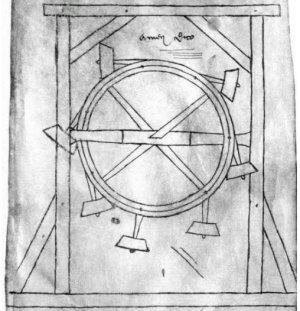       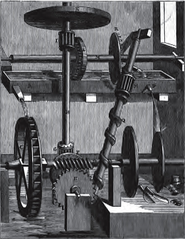

    (a)                                   (b)

(a) From the [sketchbook of Villard de Honnecourt](https://commons.wikimedia.org/wiki/File:Perpetuum_mobile_villard_de_honnecourt.jpg) (circa 1230) and (b) is a [sketch by George A. Bockler](https://commons.wikimedia.org/wiki/File:WaterScrewPerpetualMotion.png) (circa 1660)

## References

[1] Xue TW, Guo ZY. [What Is the Real Clausius Statement of the Second Law of Thermodynamics?](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC7514258) Entropy (Basel). 2019 Sep 24;21(10):926. doi: 10.3390/e21100926. PMCID: PMC7514258.

[2] Christopher Wadlow, Patents for perpetual motion machines, *Journal of Intellectual Property Law & Practice*, Volume 2, Issue 3, MARCH 2007, Pages 136–144, [https://doi.org/10.1093/jiplp/jpl242](https://doi.org/10.1093/jiplp/jpl242)

[⇦ Return to the navigation page](matlab: OpenOverview)

## Helper Functions

If you want to see the details of the code, select the **View** tab and switch to **Output Inline**. Alternately, select **Output inline **using the icon   at the top right of the Live Editor pane.

function checkTry1(myAns,prob)
if myAns == "unknown"
    disp("That is the default value. Please select an option from the drop-down.")
elseif prob == 1
    if myAns == "source"
        disp("That is correct. The air in the room is a thermal reservoir acting as a heat sink.")
    else
        disp("That is incorrect. Please try again.")
    end
elseif prob == 2
    if myAns == "sink"
        disp("That is correct. The air in the room is a thermal reservoir acting as a heat source.")
    else
        disp("That is incorrect. Please try again.")
    end
elseif prob == 3
    if myAns == "source"
        disp("That is correct. As electricity passes through the wire the resistance dissipates some of the energy as heat.")
    else
        disp("That is incorrect. Please try again.")
    end
else
    warning("How did you get here?")
end
end

function checkSystem(myAns,opt)
if opt == "a"
        if myAns == "unclassifiable"
            fdbk = "This is the default value. This system is classifiable.";
        elseif myAns == "adiabatic"
            fdbk = "Yes, the entire universe is adiabatic. Why?";
        elseif myAns == "not adiabatic"
            fdbk = "If the universe is not adiabatic, it must exchange heat with something." + ...
                newline + "What is outside the universe that could receive that heat?";
        end
        restatement = "You said the system is " + myAns + ".";
elseif myAns == "default"
    fdbk  = "This is the default value. Please answer the question.";
    restatement = "You said the entire universe is ?";
else
    str = "You said the rest of the universe is";
    switch opt
        case "b"
            tf = myAns == "hotter";
            fdbk = giveFeedback(tf);
            if ~tf
                fdbk = fdbk + newline + "If the coffee is getting colder, where did the heat go?";
            end
        case "c"
            tf = myAns == "colder";
            fdbk = giveFeedback(tf);
            if ~tf
                fdbk = fdbk + newline + "If the coffee is getting warmer, where did the come from?";
            end
        case "d"
            tf = myAns == "constant";
            fdbk = giveFeedback(tf);
            if tf
                fdbk = fdbk + "Let's assume the coffee starts cold." + ...
                    newline + "As it warms, it pulls heat from the rest of the universe. Then" + ...
                    newline + "as it cools, it returns heat back to the rest of the universe." + ...
                    newline + "The total amount of energy in the universe is constant.";
            else
                fdbk = fdbk + "Remember that this is a cycle." + ...
                    newline + "Can the Kelvin-Planck statement help you here?";
            end
    end
    switch myAns
        case "hotter"
            restatement = str + " getting hotter.";
            fdbk = fdbk + newline + "When the universe is getting hotter, where did the heat come from?";
        case "colder"
            restatement = str + " getting colder.";
            fdbk = fdbk + newline + "When the universe is getting colder, where did the heat go?";
        case "constant"
            restatement = str + " contains the same amount of heat energy."; 
            fdbk = fdbk + newline + "When the temperature of the universe is constant, can it exchange" + ...
                newline + "heat with the cup of coffee?";
        otherwise
            restatement = str + "Why did you get here? You were answering problem " + opt + ").";
            fdbk = fdbk + "Why did you get here? Your answer was " + myAns;
    end
end
disp(restatement)
disp(fdbk)
end

function fdbk = giveFeedback(tf)
    if tf
        fdbk = "That is correct. ";
    else
        fdbk = "That is incorrect. ";
    end
end

function checkExercise2(myAns,opt)
switch opt
    case "a"
        corAns = "zero";
        corfdbk = "Because the entire universe is an adiabatic system," + ...
        newline + "the change in heat energy is 0. This forces the overall entropy change to be 0.";
    case "b"
        corAns = "negative";
        corfdbk = "The temperature of the entire universe and the" + ...
            newline + "temperature of the entire universe minus one cup of coffee are identical" + ...
            newline + "for practical purposes, and definitely positive. The heat energy, however," + ...
            newline + "must be flowing out of the universe and into the cup of coffee. This means" + ...
            newline + "that the entropy is decreasing.";
    case "c"
        corAns = "positive";
        corfdbk = "The temperature of the cup of coffee is" + ...
            newline + "positive and the heat flow 𝛿Q is positive. This means that" + ...
            newline + "the change in entropy for the cup of coffee is also positive.";
end
tf = myAns == corAns;
fdbk = giveFeedback(tf);
if tf
    fdbk = fdbk + corfdbk;
elseif myAns == "?"
    fdbk = fdbk + "This is the default value." + newline + "Please answer the question.";
elseif myAns == "positive"
    fdbk = fdbk + "The temperature T is always nonnegative, so a positive" + ...
        newline + "change in entropy means that heat is flowing into your system. Is that happening?";
elseif myAns == "negative"
        fdbk = fdbk + "The temperature T is always nonnegative, so a negative" + ...
        newline + "change in entropy means that heat is flowing out of your system. Is that happening?";
elseif myAns == "zero"
        fdbk = fdbk + "The temperature T is always nonnegative, so no" + ...
        newline + "change in entropy means that either no heat is flowing or that heat" + ...
        newline + "flows are exactly balanced. Is that happening?";
else
    warning("How did you get here?")
end

disp(fdbk)
end